# Taratura del controllo di velocità lato motore - Cancellazione polo-zero

Importo il modello lineare del sistema motore-trasmissione elastica-carico

clear all;close all;clc;
Jm=2e-2;
Jc=10e-2;
k=1000;
h=0.3;
hm=.001;
model=ElasticSystemModel(Jm,Jc,k,h,hm)


model =
 
  A = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Pos. motore            0            0            1            0
   Po. carico             0            0            0            1
   Vel. motore       -5e+04        5e+04       -15.05           15
   Vel. carico        1e+04       -1e+04            3           -3
 
  B = 
                tau motore  tau carico
   Pos. motore           0           0
   Po. carico            0           0
   Vel. motore          50           0
   Vel. carico           0          10
 
  C = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Pos. motore            1            0            0            0
   Pos. carico            0            1            0            0
   Vel. motore            0            0            1            0
   Vel. carico            0            0            0            1
 
  D = 
                tau motore  tau carico
   Pos. motore           0           0
   Pos. cari

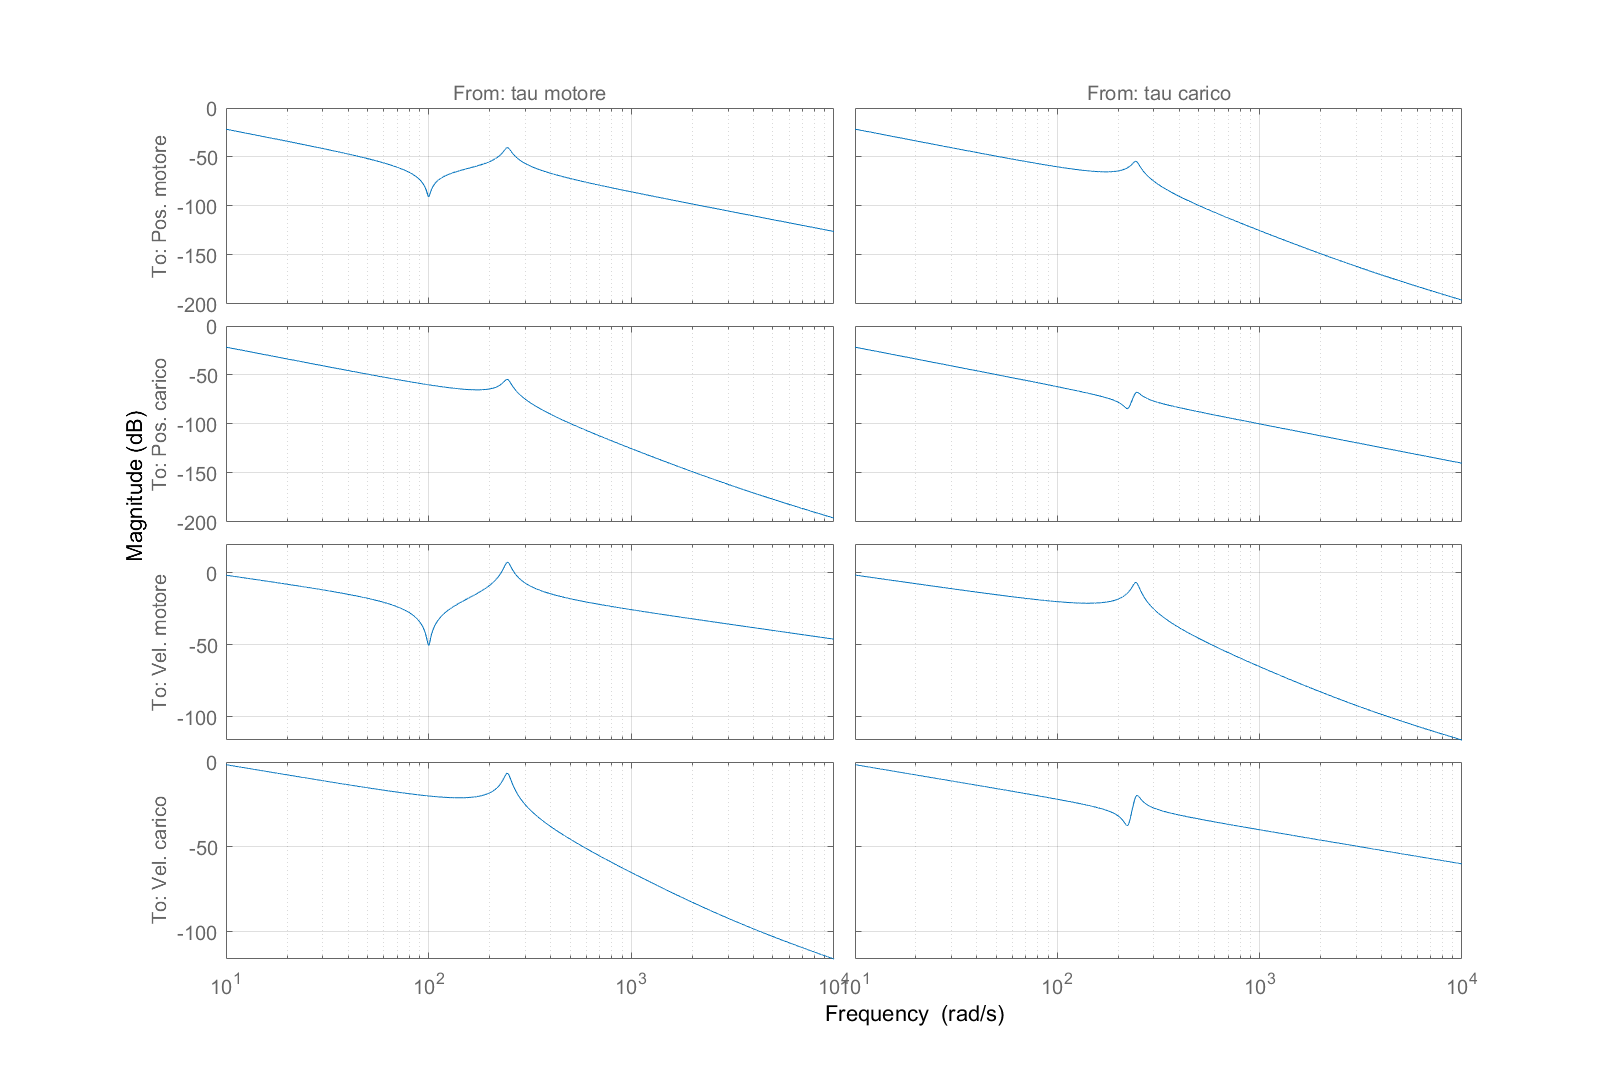

figure('Name','Diagramma di bode','Position',[1 1 1200 800])
omega=logspace(1,4,1e4);
bodemag(model,omega)
grid on

### Modello di velocità del motore

La conversione da state-space a transfer function può dare errori numerici. In particolare il polo nell'origine può venire spostato leggermente a sinistra (quindi a parte reale negativa), o leggermente a destra (instabile!). è più robusto passare prima a zpk e poi tf

tf(model(3,1))


ans =
 
  From input "tau motore" to output "Vel. motore":
            50 s^3 + 150 s^2 + 5e05 s
  ----------------------------------------------
  s^4 + 18.05 s^3 + 6e04 s^2 + 500 s + 5.025e-08
 
Continuous-time transfer function.



sys_vel_motore=zpk(model(3,1)) % zpk è più precisa


sys_vel_motore =
 
  From input "tau motore" to output "Vel. motore":
         50 s (s^2 + 3s + 1e04)
  ------------------------------------
  s (s+0.008333) (s^2 + 18.04s + 6e04)
 
Continuous-time zero/pole/gain model.



sys_vel_motore=minreal(sys_vel_motore) % semplifico poli e zeri coincidenti se ci sono


sys_vel_motore =
 
  From input "tau motore" to output "Vel. motore":
         50 (s^2 + 3s + 1e04)
  ----------------------------------
  (s+0.008333) (s^2 + 18.04s + 6e04)
 
Continuous-time zero/pole/gain model.



sys_vel_motore.DisplayFormat='TimeConstant' % la fattorizzazione nelle costanti di tempo risulta più comoda


sys_vel_motore =
 
  From input "tau motore" to output "Vel. motore":
         1000 (1 + 0.03(0.01s) + (0.01s)^2)
  -------------------------------------------------
  (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
 
Continuous-time zero/pole/gain model.



damp(sys_vel_motore)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.33e-03                 1.00e+00       8.33e-03         1.20e+02    
 -9.02e+00 + 2.45e+02i     3.68e-02       2.45e+02         1.11e-01    
 -9.02e+00 - 2.45e+02i     3.68e-02       2.45e+02         1.11e-01    


[zeri,poli,costante_sys]=zpkdata(sys_vel_motore)

zeri = 1×1 cell array
    {2×1 double}


poli = 1×1 cell array
    {3×1 double}


costante_sys = 50

zeri{1}

ans =   -1.5000 +99.9887i
  -1.5000 -99.9887i


poli{1}

ans = 	1.0e+02 *

  -0.0902 + 2.4478i
  -0.0902 - 2.4478i
  -0.0001 + 0.0000i


costante_sys

costante_sys = 50

dcgain(sys_vel_motore)

ans = 1.0000e+03

### Cancellazione polo-zero

Il controllore è una funzione di trasferimento con poli e zeri e una costante di tempo.

Posso usare questi poli e zeri per cancellare zeri e poli del processo e usare la costante per scegliere la frequenza di taglio desiderata o il margine di fase.

zeri del controllore  = poli  del sistema

poli del controllore = zero del sistema +  polo nell'origine + poli in alta frequenza

%% Controllore cancellazione polo zero
gain=5.5;
zeri_da_cancellare=[];
poli_da_cancellare=poli{1};
poli_controllore=[-200;0;-200];
C_vel=zpk(poli_da_cancellare,poli_controllore,gain,'DisplayFormat','TimeConstant');
C_vel.InputName='rad/s'


C_vel =
 
  From input "rad/s" to output:
  0.06875 (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
  ---------------------------------------------------------
                       s (1+0.005s)^2
 
Continuous-time zero/pole/gain model.



C_vel.OutputName='Coppia motore'


C_vel =
 
  From input "rad/s" to output "Coppia motore":
  0.06875 (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
  ---------------------------------------------------------
                       s (1+0.005s)^2
 
Continuous-time zero/pole/gain model.



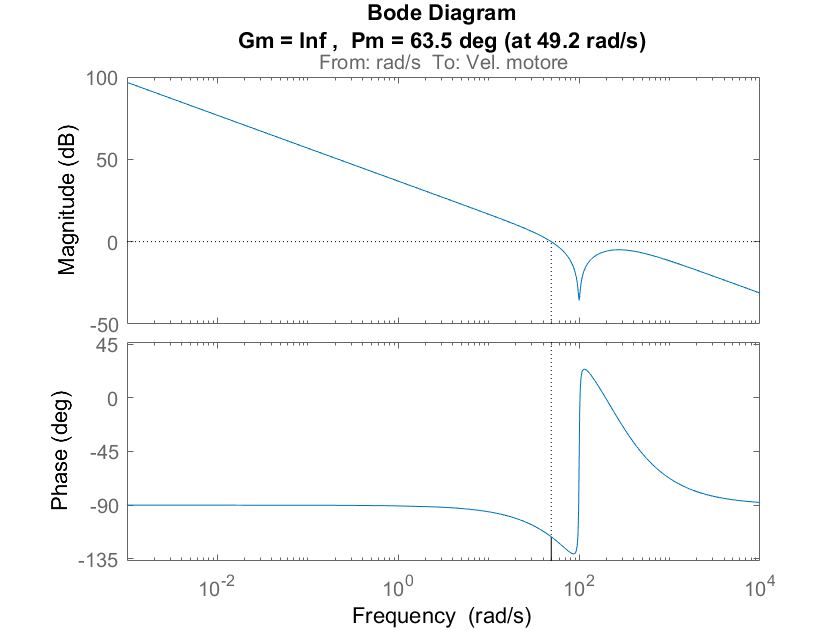

L_vel_motore=sys_vel_motore*C_vel;
figure
margin(L_vel_motore)

Tuttavia la cancellazione polo-zero non elimina veramente la dinamica del sistema che rimane comunque presente nella funzione di trasferimento fra disturbo e uscita.

$L=PC$ poli e zeri di $P$ e $C$ si cancellano

$F=\frac{Y}{R}=\frac{PC}{1+PC}$  poli e zeri di $P$ e $C$ si cancellano

$\frac{Y}{D}=\frac{P}{1+PC}=\frac{F}{C}$  i poli di $P$ rimangono!

**Nota**: 

minreal cancella poli e zeri coincidenti presenti nello stesso sistema

il tuning chiamato "cancellazione polo/zero" cancella poli e zeri di due sistemi diversi.

Y_sp_vel_motore=feedback(sys_vel_motore*C_vel,1); % setpoint velocita => velocita
Y_sp_vel_motore=minreal(Y_sp_vel_motore) %semplifico poli e zeri


Y_sp_vel_motore =
 
  From input "rad/s" to output "Vel. motore":
             (1 + 0.03(0.01s) + (0.01s)^2)
  ---------------------------------------------------
  (1+0.0003902s) (1 + 0.161(0.01085s) + (0.01085s)^2)
 
Continuous-time zero/pole/gain model.




U_sp_vel_motore=minreal(zpk(feedback(C_vel,sys_vel_motore))) % setpoint velocità => coppia


U_sp_vel_motore =
 
  From input "rad/s" to output "Coppia motore":
  0.001 (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
  -------------------------------------------------------
    (1+0.0003902s) (1 + 0.161(0.01085s) + (0.01085s)^2)
 
Continuous-time zero/pole/gain model.



Y_dist_vel_motore=minreal(zpk(feedback(sys_vel_motore,C_vel))) % disturbo => velocita


Y_dist_vel_motore =
 
  From input "tau motore" to output "Vel. motore":
                           1.837 s (1+0.005s)^2 (1 + 0.03(0.01s) + (0.01s)^2)
  -----------------------------------------------------------------------------------------------------
  (1+0.0003902s) (1+120s) (1 + 0.161(0.01085s) + (0.01085s)^2) (1 + 0.07365(0.004082s) + (0.004082s)^2)
 
Continuous-time zero/pole/gain model.



U_dist_vel_motore=minreal(zpk(-feedback(C_vel*sys_vel_motore,1))) % disturbo => coppia


U_dist_vel_motore =
 
  From input "tau motore" to output "Coppia motore":
            - (1 + 0.03(0.01s) + (0.01s)^2)
  ---------------------------------------------------
  (1+0.0003902s) (1 + 0.161(0.01085s) + (0.01085s)^2)
 
Continuous-time zero/pole/gain model.



A causa della presenza dei poli "cancellati" nella funzione di trasferimento *disturbo => velocita* la risposta al disturbo è oscillante e lenta.

La cancellazione polo-zero va effettuata quando la reiezione dei disturbi non è importante (perchè sono pochi, perchè un anello interno li compensa...) 

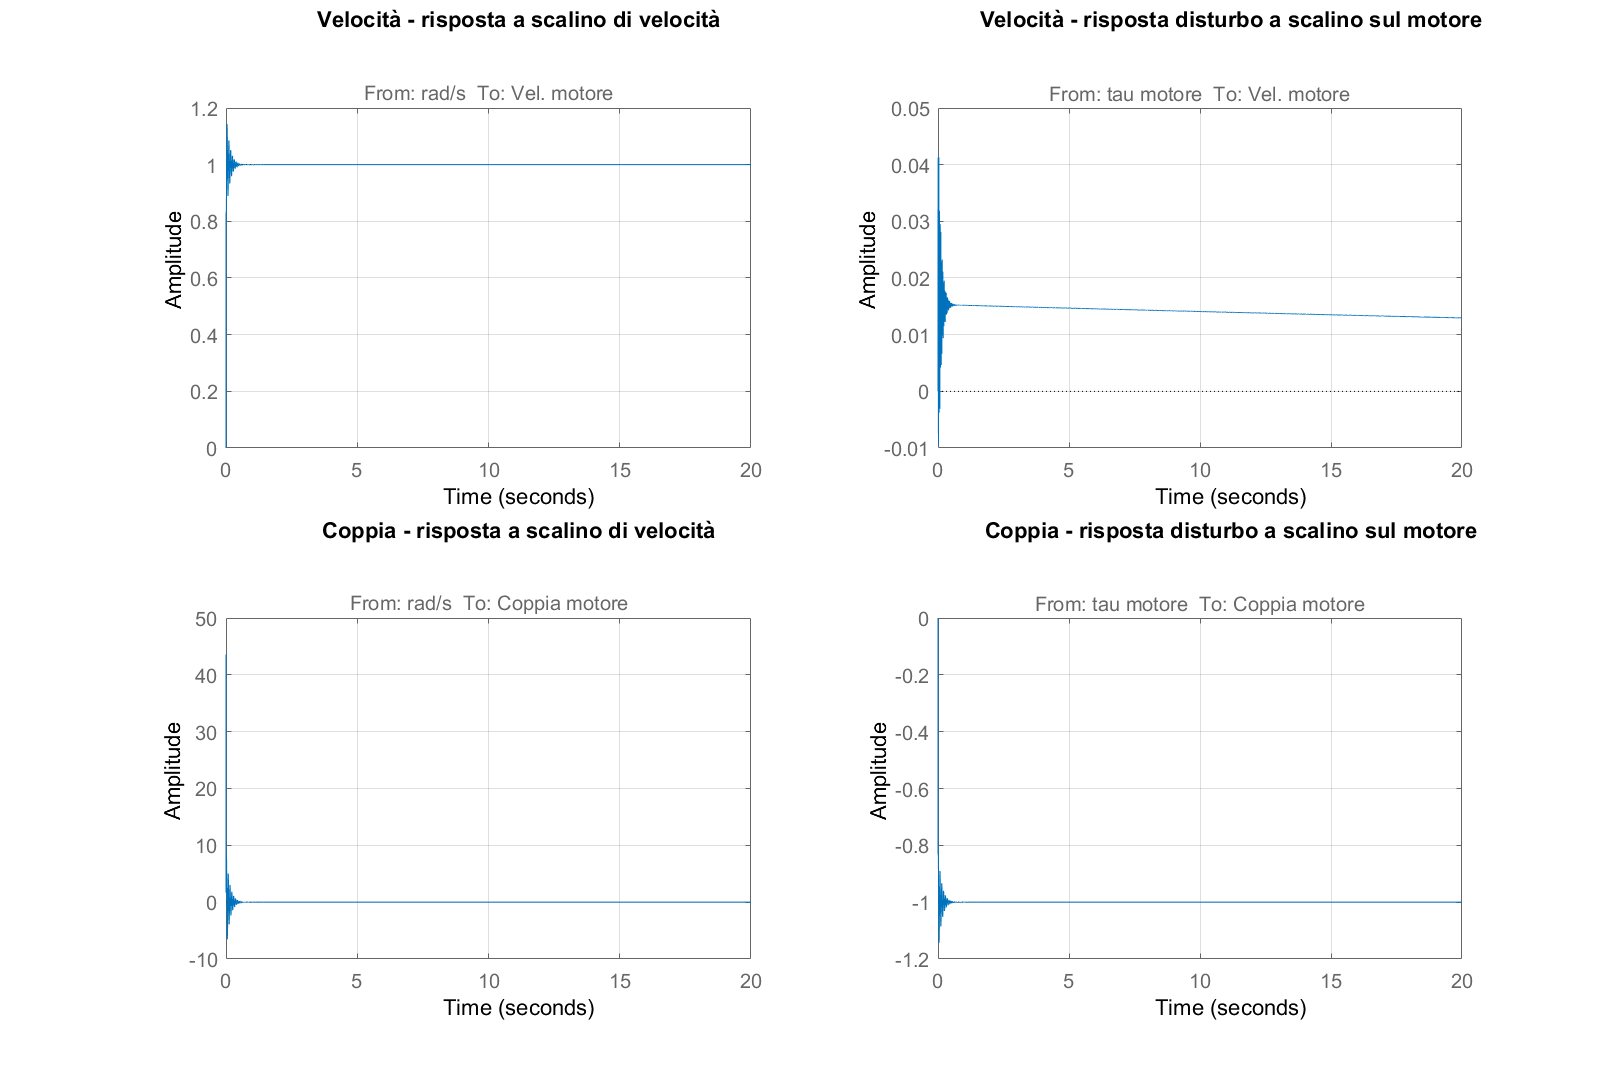

t=(0:1e-3:20)';
% risposta allo scalino sul setpoint velocità
figure('Name','Cancellazione polo-zero','Position',[1 1 1200 800])
handle(1)=subplot(2,2,1);
step(Y_sp_vel_motore,t)
title('Velocità - risposta a scalino di velocità')
grid on
handle(2)=subplot(2,2,3);
step(U_sp_vel_motore,t)
title('Coppia - risposta a scalino di velocità')
grid on

handle(3)=subplot(2,2,2);
step(Y_dist_vel_motore,t)
title('Velocità - risposta disturbo a scalino sul motore')
grid on
handle(4)=subplot(2,2,4);
step(U_dist_vel_motore,t)
title('Coppia - risposta disturbo a scalino sul motore')
grid on

linkaxes(handle,'x') % stessa scala temporale su tutti i grafici
xlim([0 20])

### Effetto dell'errore di modellazione

supponiamo di avere un errore di modellazione

perturbazione=0.9;
modello_perturbato=ElasticSystemModel(Jm,Jc*perturbazione,k,h,hm);
sys_vel_motore_perturbato = zpk(modello_perturbato(3,1));
sys_vel_motore_perturbato.DisplayFormat='TimeConstant'


sys_vel_motore_perturbato =
 
  From input "tau motore" to output "Vel. motore":
    1000 s (1 + 0.03162(0.009487s) + (0.009487s)^2)
  ---------------------------------------------------
  s (1+110s) (1 + 0.07433(0.004045s) + (0.004045s)^2)
 
Continuous-time zero/pole/gain model.



sys_vel_motore=zpk(sys_vel_motore);
sys_vel_motore.DisplayFormat='TimeConstant'


sys_vel_motore =
 
  From input "tau motore" to output "Vel. motore":
         1000 (1 + 0.03(0.01s) + (0.01s)^2)
  -------------------------------------------------
  (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
 
Continuous-time zero/pole/gain model.



Y_sp_vel_motore_perturbato=feedback(sys_vel_motore_perturbato*C_vel,1); % setpoint velocita => velocita
Y_sp_vel_motore_perturbato=minreal(Y_sp_vel_motore_perturbato) %semplifico poli e zeri


Y_sp_vel_motore_perturbato =
 
  From input "rad/s" to output "Vel. motore":
        (1 + 0.03162(0.009487s) + (0.009487s)^2) (1 + 0.07365(0.004082s) + (0.004082s)^2)
  ---------------------------------------------------------------------------------------------
  (1+0.0003902s) (1 + 0.1544(0.01031s) + (0.01031s)^2) (1 + 0.07435(0.004076s) + (0.004076s)^2)
 
Continuous-time zero/pole/gain model.



la cancellazione polo-zero non avviene più

U_sp_vel_motore_perturbato=feedback(C_vel,sys_vel_motore_perturbato); % setpoint velocita => coppia

Y_dist_vel_motore_perturbato=feedback(sys_vel_motore_perturbato,C_vel) % disturbo => velocita


Y_dist_vel_motore_perturbato =
 
  From input "tau motore" to output "Vel. motore":
                      1.837 s^2 (1+0.005s)^2 (1 + 0.03162(0.009487s) + (0.009487s)^2)
  --------------------------------------------------------------------------------------------------------
  s (1+0.0003902s) (1+120s) (1 + 0.1544(0.01031s) + (0.01031s)^2) (1 + 0.07435(0.004076s) + (0.004076s)^2)
 
Continuous-time zero/pole/gain model.



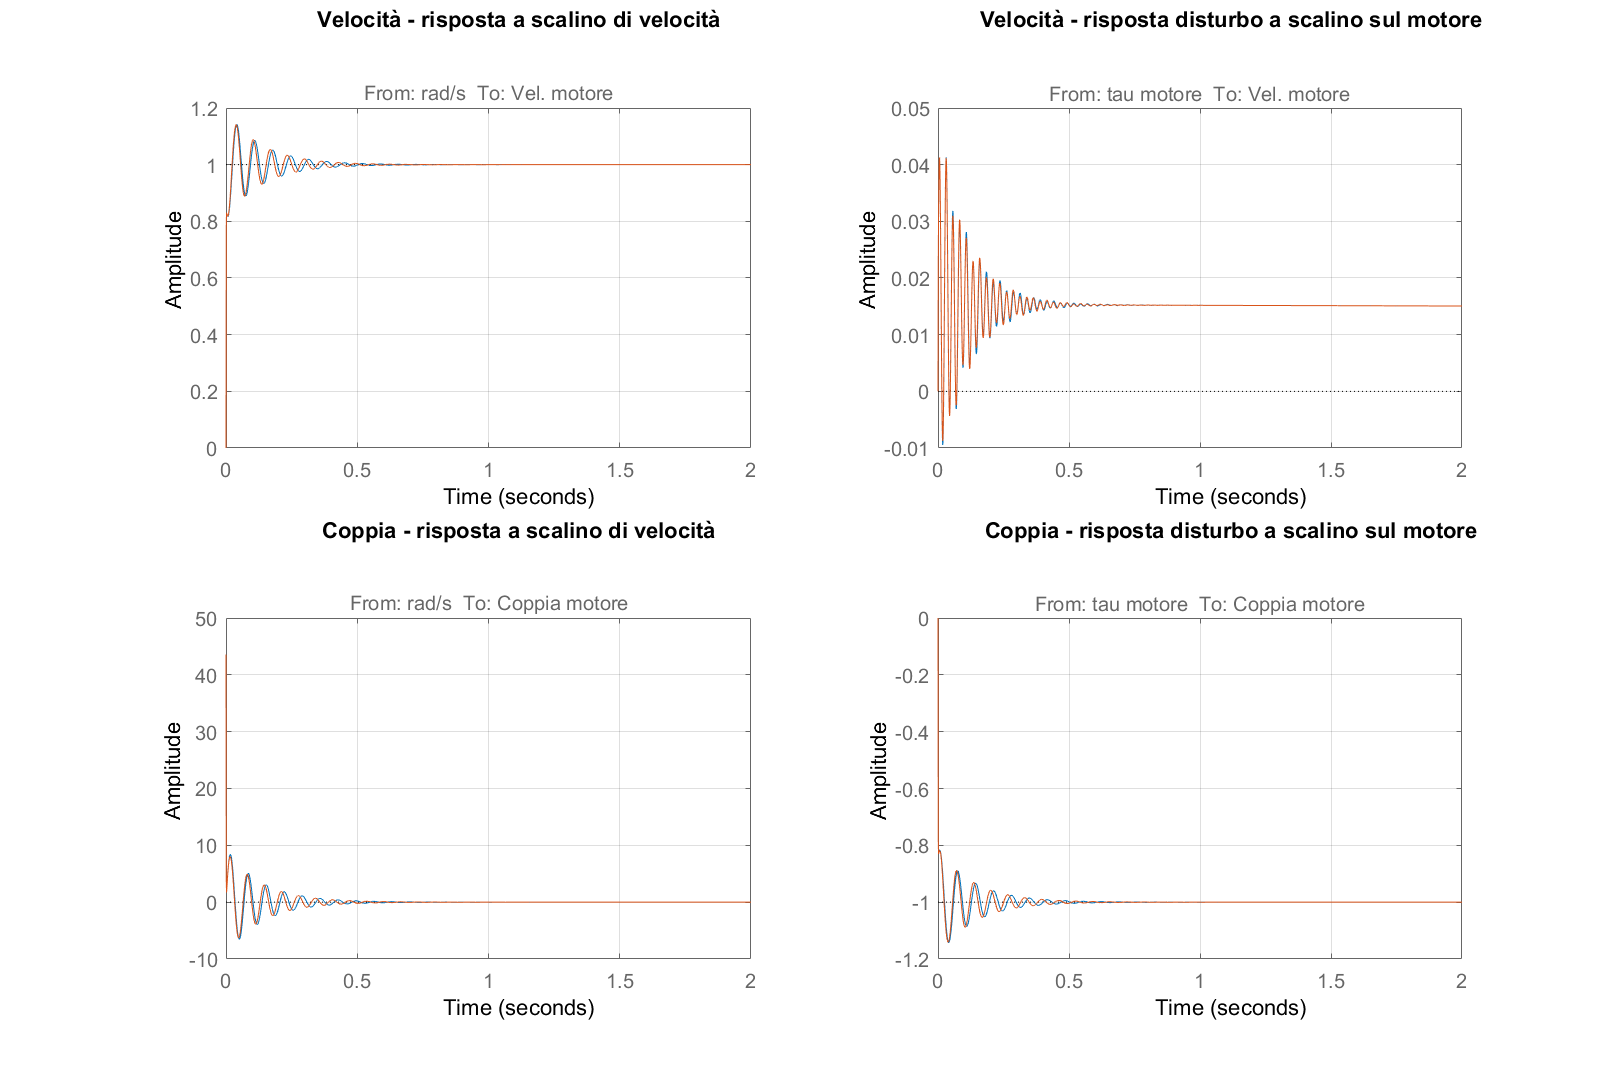

U_dist_vel_motore_perturbato=-feedback(C_vel*sys_vel_motore_perturbato,1); % disturbo => coppia
% risposta allo scalino sul setpoint velocità
figure('Name','Cancellazione polo-zero su sistema perturbato','Position',[1 1 1200 800])
handle(1)=subplot(2,2,1);
step(Y_sp_vel_motore,Y_sp_vel_motore_perturbato,t)
title('Velocità - risposta a scalino di velocità')
grid on
handle(2)=subplot(2,2,3);
step(U_sp_vel_motore,U_sp_vel_motore_perturbato,t)
title('Coppia - risposta a scalino di velocità')
grid on

handle(3)=subplot(2,2,2);
step(Y_dist_vel_motore,Y_dist_vel_motore_perturbato,t)
title('Velocità - risposta disturbo a scalino sul motore')
grid on
handle(4)=subplot(2,2,4);
step(U_dist_vel_motore,U_dist_vel_motore_perturbato,t)
title('Coppia - risposta disturbo a scalino sul motore')
grid on

linkaxes(handle,'x') % stessa scala temporale su tutti i grafici
xlim([0 2])

### Isolare l'azione integrale dal resto

una volta tarato il controllore, ci interessa è isolare la parte integrale dal resto per poter implementare l'antiwindup. Quindi dobbiamo riscrivere


$$C(s)=\frac{K_i}{s}+C_{0}(s)$$


C_vel


C_vel =
 
  From input "rad/s" to output "Coppia motore":
  0.54437 (1+120s) (1 + 0.07365(0.004082s) + (0.004082s)^2)
  ---------------------------------------------------------
                       s (1+0.005s)^2
 
Continuous-time zero/pole/gain model.



[numC,denC]=tfdata(C_vel) % calcolo numetore e denomitore

numC = 1×1 cell array
    {1×4 double}


denC = 1×1 cell array
    {1×4 double}


numC{1}

ans = 	1.0e+06 *

    0.0000    0.0008    2.6130    0.0218


help residue

 residue Partial-fraction expansion (residues).
    [R,P,K] = residue(B,A) finds the residues, poles and direct term of
    a partial fraction expansion of the ratio of two polynomials B(s)/A(s).
    If there are no multiple roots,
       B(s)       R(1)       R(2)             R(n)
       ----  =  -------- + -------- + ... + -------- + K(s)
       A(s)     s - P(1)   s - P(2)         s - P(n)
    Vectors B and A specify the coefficients of the numerator and
    denominator polynomials in descending powers of s.  The residues
    are returned in the column vector R, the pole locations in column
    vector P, and the direct terms in row vector K.  The number of
    poles is n = length(A)-1 = length(R) = length(P). The direct term
    coefficient vector is empty if length(B) < length(A), otherwise
    length(K) = length(B)-length(A)+1.
 
    If P(j) = ... = P(j+m-1) is a pole of multplicity m, then the
    expansion includes terms of the form
            

[res,poliC,costante]=residue(numC{1},denC{1}) % scomposizione in fratti semplici

res = 	1.0e+06 *

   -0.0166
    4.1977
    0.0000


poliC =  -200.0000
 -200.0000
         0


costante = 43.5500

Ki=res(3)

Ki = 0.5444

s=tf('s');
C0=minreal(C_vel-Ki/s) % parte del controllore esclusa l'azione integrale


C0 =
 
  From input "rad/s" to output "Coppia motore":
  65.32 (1 + 0.07364(0.004083s) + (0.004083s)^2)
  ----------------------------------------------
                   (1+0.005s)^2
 
Continuous-time zero/pole/gain model.



### Cancellare l'antirisonanza è intelligente?

Analizziamo la risposta in frequenza delle funzioni di trasferimento:

sys_vel_motore=model(3,1)


sys_vel_motore =
 
  A = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Pos. motore            0            0            1            0
   Po. carico             0            0            0            1
   Vel. motore       -5e+04        5e+04       -15.05           15
   Vel. carico        1e+04       -1e+04            3           -3
 
  B = 
                tau motore
   Pos. motore           0
   Po. carico            0
   Vel. motore          50
   Vel. carico           0
 
  C = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Vel. motore            0            0            1            0
 
  D = 
                tau motore
   Vel. motore           0
 
Continuous-time state-space model.



sys_vel_carico=model(4,1)


sys_vel_carico =
 
  A = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Pos. motore            0            0            1            0
   Po. carico             0            0            0            1
   Vel. motore       -5e+04        5e+04       -15.05           15
   Vel. carico        1e+04       -1e+04            3           -3
 
  B = 
                tau motore
   Pos. motore           0
   Po. carico            0
   Vel. motore          50
   Vel. carico           0
 
  C = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico
   Vel. carico            0            0            0            1
 
  D = 
                tau motore
   Vel. carico           0
 
Continuous-time state-space model.



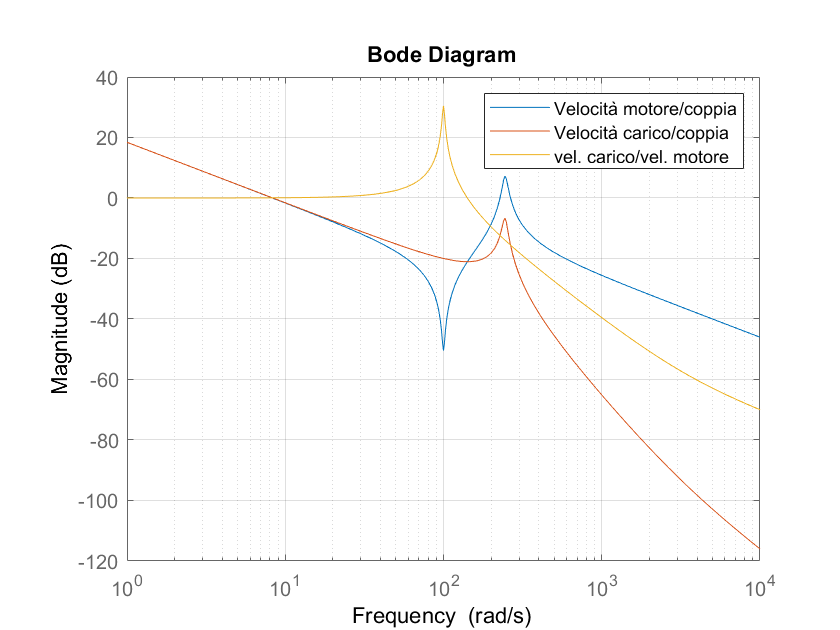

figure 
bodemag(sys_vel_motore,sys_vel_carico,sys_vel_carico/sys_vel_motore)
xlim([1 1e4])
legend({'Velocità motore/coppia','Velocità carico/coppia','vel. carico/vel. motore'})
grid on

La antirisonanza del motore è vicina alla risonanza del carico.

sistema_retrazionato=feedback(model*[C_vel;0],[0 0 1 0])


sistema_retrazionato =
 
  A = 
                Pos. motore   Po. carico  Vel. motore  Vel. carico            ?            ?            ?
   Pos. motore            0            0            1            0            0            0            0
   Po. carico             0            0            0            1            0            0            0
   Vel. motore       -5e+04        5e+04       -290.1           15        12.55    4.269e+04       -169.2
   Vel. carico        1e+04       -1e+04            3           -3            0            0            0
   ?                      0            0      -0.1826            0            0        28.34      -0.1123
   ?                      0            0            0            0            0         -200            1
   ?                      0            0       -620.9            0            0            0         -200
 
  B = 
                 rad/s
   Pos. motore       0
   Po. carico        0
   Vel. motore     275
   Vel. carico    

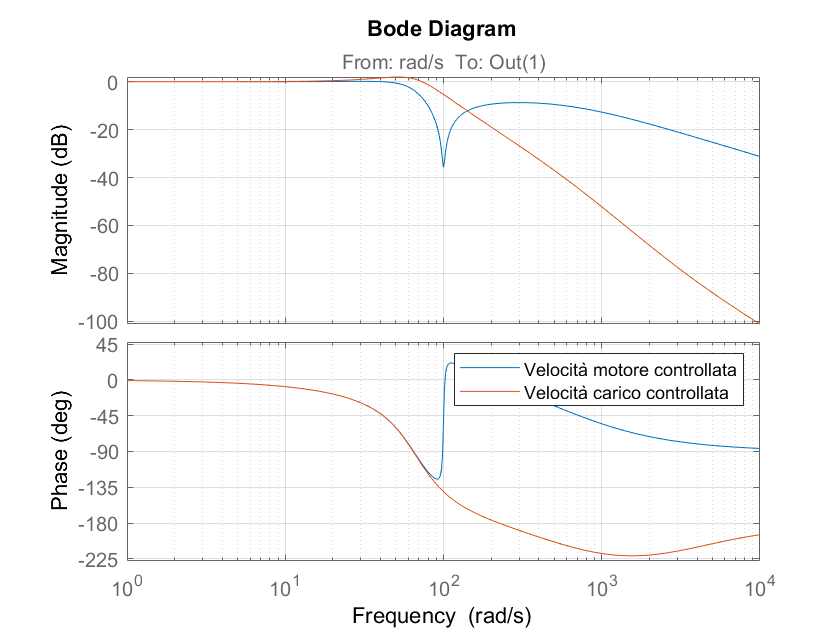

figure
bode(sistema_retrazionato(3),sistema_retrazionato(4))
xlim([1 1e4])
legend({'Velocità motore controllata','Velocità carico controllata'})
grid on

In un sistema controllato dal lato del motore, più il motore è "rigido" (cioè la sua banda passante è alta), più il carico risuona.